# A Temporal Gaussian Noise Model for Equalization-enhanced Phase Noise (EEPN)

In this script, we provide an implementation of our proposed temporal Gaussian noise model for equalization-enhanced phase noise model, which we presented at the European Conference on Optical Communication (ECOC) in Copenhagen in October 2025:

[B. Geiger, F. Buchali, V. Aref, and L. Schmalen, "A Temporal Gaussian Noise Model for Equalization-enhanced Phase Noise" In Proc. European Conference on Optical Communication (ECOC), Copenhagen, Denmark, 2025, Tu01.05.3](https://arxiv.org/abs/2507.08470).

In particular, we compare our temporal Gaussian noise model to a full system simulation and show that we can obtain and generate the same system performance with less code, less computational complexity and much faster.

**Possible applications of our model include:**

- Accurate and low-complexity performance prediction

- Baseline for EEPN mitigation algorithms

- Modeling impaired links (using our model in a generative manner)

## Parameters

symbol_rate = 130e9;                    % Symbol Rate in Baud
linewidth = 210e3;                      % Linewidth of the local oscillator (LO) in Hertz
fiber_length = 1900;                    % Fiber length in km

mod_order = 16;                         % Modulation format
oversampling_factor = 2;                % Oversampling factor

RRC_roll_off = 0.01;                    % RRC Roll-off factor (Pulse shaping & matched filter)
RRC_span = 100;                         % RRC span (Pulse shaping & matched filter)

snr = 13;                               % Signal-to-noise ratio in dB

num_transmission_symbols = 1e7;         % Number of modulation symbols to transmit

D_cd = 18.957e-12/(1e-9);               % Chromatic Dispersiopn Parameter in s/(km*m)
lambda = 1.55e-6;                       % Center Wavelength in m
c_0 = 3e8;                              % Vacuum speed of light in m/s

CPR_window_length = 50;                 % Window length of the carrier phase recovery (CPR): here ideal data-remodulation in symbols

block_length_SNR_evaluation = 500;      % Number of symbols which are used to estimate the SNR after the transmission

t = [0:num_transmission_symbols-1]/symbol_rate; % Time vector

df = symbol_rate/num_transmission_symbols; % frequncy resolution
f = [-num_transmission_symbols*oversampling_factor/2:1:num_transmission_symbols*oversampling_factor/2-1]*df; % Frequency vector

% Calculate the temporal broadening a pulse due to chromatic dispersion
D = D_cd*fiber_length;                  % Temporal broadening/accumulated dispersion in ns/nm
Delta_lambda = (lambda)^2/c_0*symbol_rate; % Sepctral width in wavelength
Delta_T = D*Delta_lambda;               % Temporal broadening/accumulated dispersion in s
CD_memory = round((Delta_T*130e9));     % Temporal broadening/CD memory in samples

discard_symbols_analysis = 2*CD_memory;   % Number of symobls which are discarded in the analysis at the start and end of a sequence

## LO Phase Noise

In this script, we model the LO phase noise as a Wiener process. However, here you could also loud your measured LO phase noise realization like we did in our paper or generate any other LO phase realization. Our proposed temporal Gaussian noise model does not make any assumptions about the LO phase noise statistics.

% Variance of the Wiener process
sigma2_LO = 2*pi*linewidth*1/(oversampling_factor*symbol_rate);

% Sample increments
Rx_delta_phi = sqrt(sigma2_LO)*randn(num_transmission_symbols*oversampling_factor,1);

% Calculate LO phase realization
Rx_phi = cumsum(Rx_delta_phi)+2*pi*rand(1);

## Full System Simulation

#### Transmitter

In the transmitter, we choose Tx symbols uniformly, upsample and apply a pulse shaping filter

% Generate transmit symbols
Tx_symbols = qammod(randi(mod_order,num_transmission_symbols,1)-1, mod_order,"UnitAveragePower",true);

% Upsample the transmit symbols by a factor of n
Tx_symbols_up = upsample(Tx_symbols, oversampling_factor);

% Create the pulse shaping filter
rrcFilter = rcosdesign(RRC_roll_off, RRC_span, oversampling_factor).';

% Apply the pulse shaping filter
Tx_signal = conv(Tx_symbols_up, rrcFilter,'same');

#### Channel

We pass the transmit signal through a chromatic dispersion (CD) filter and add AWGN to account for amplified spontaneous emission, fiber nonlinearity and transceiver impairments.

% Initialze CD filter
H_cd = exp(1j*pi*lambda^2/c_0*D_cd*fiber_length*f.^2).';     % Frequency response of the fiber

% Apply CD filter (model dispersive fiber)
dispersed_signal = ifft(fftshift(H_cd.*fftshift(fft(Tx_signal))));

% Add noise
system_noise_power = 10^(-snr/10);
Rx_signal = dispersed_signal + sqrt(system_noise_power/2)*randn(size(Tx_signal))+1j*sqrt(system_noise_power/2)*randn(size(Tx_signal));

#### Receiver

In the receiver, the signal is first impaired by phase noise due to the finite linewidth of the laser. Next, we apply the chromatic dispersion compensation (CDC) filter and matched filter. Then, we downsample and estimate the phase using ideal data remodulation (A. Arnould and A. Ghazisaeidi, “Equalization Enhanced Phase Noise in Coherent Receivers: DSP-Aware Analysis and Shaped Constellations”, Journal of Lightwave Technology, vol. 37, no. 20, pp. 5282–5290, Oct. 2019).

% Apply LO noise (due to finite linewidth of the LO)
Rx_signal_with_phase_noise = Rx_signal.*exp(1j*Rx_phi);

% CD compensation
Rx_signal_cdc = ifft(fftshift(fftshift(fft(Rx_signal_with_phase_noise)).*conj(H_cd)));

% Apply matched filter
Rx_symbols_up = conv(Rx_signal_cdc, rrcFilter,'same');

% Downsample
Rx_symbols = Rx_symbols_up(1:2:end);

% Estimate the phase offset using ideal data remodulation
phase_est = angle(movmean(conj(Tx_symbols).*Rx_symbols, CPR_window_length));

% Correct the estimated phase error
Rx_symbols_CPR = Rx_symbols.*exp(-1j*phase_est);

Here, we show the LO phase noise realization, the estimated LO phase noise (using ideal data remodulation) and the mean frequecy-dependent phase noise which is given by the sliding mean of the LO phase with the CD memory as window length.

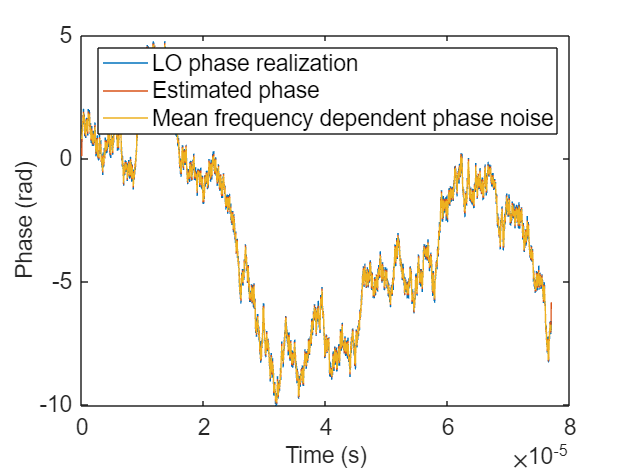

figure();
title("LO phase and its estimate over time")
plot(t, Rx_phi(1:2:end)); hold on; plot(t, unwrap(phase_est)); plot(t, movmean(Rx_phi(1:2:end), CD_memory+1));
legend(["LO phase realization", "Estimated phase", "Mean frequency dependent phase noise"])
xlabel("Time (s)"); ylabel("Phase (rad)"); fontsize(15,"points")

When you zoom in, you can observe that the estimated phase does not longer follow the LO phase noise but the mean frequency-dependent phase noise given by the sliding mean of the LO phase noise.

#### Evaluation

Finally, we calculate the distortion and noise power in the simulation

sigma_simulation = movvar(Rx_symbols_CPR-Tx_symbols, block_length_SNR_evaluation);
sigma_simulation(1:discard_symbols_analysis) = [];
sigma_simulation(end:end-discard_symbols_analysis) = [];

## Temporal Gaussian Noise Model for Equalization-enhanced Phase Noise

In this section, we provide an implementation of our proposed temporal Gaussian noise model

% Calculate the EEPN distortion power
sigma_EEPN = movvar(Rx_phi(1:2:end), CD_memory+1);

% Calculate time-varying distortion power
sigma_time_varying = system_noise_power + sigma_EEPN;

**Comment****: **We can now either use directly the calculated distortion power for the evaluation (less noisy) or we can use our model in a generative manner to generate noisy received symbols modeling an EEPN-impaired link.

% Sample AWGN from time-varying distortion power and add to transmit signal
Rx_symbols_TGN = Tx_symbols + sqrt(sigma_time_varying/2).*(randn(size(Tx_symbols))+1j*randn(size(Tx_symbols)));

#### Evalutation

% Cut the directly calculated distortion power
sigma_time_varying(1:discard_symbols_analysis) = [];
sigma_time_varying(end:end-discard_symbols_analysis) = [];

% Calculate and cut the distortion power in case the model is used in a
% generative manner
sigma_TGN = movvar(Rx_symbols_TGN-Tx_symbols, block_length_SNR_evaluation);
sigma_TGN(1:discard_symbols_analysis) = [];
sigma_TGN(end:end-discard_symbols_analysis) = [];

## Comparison

In this section, we compare the temporal Gaussian noise model to the full-system simulation.

#### Illustrative SNR/Variance sequence

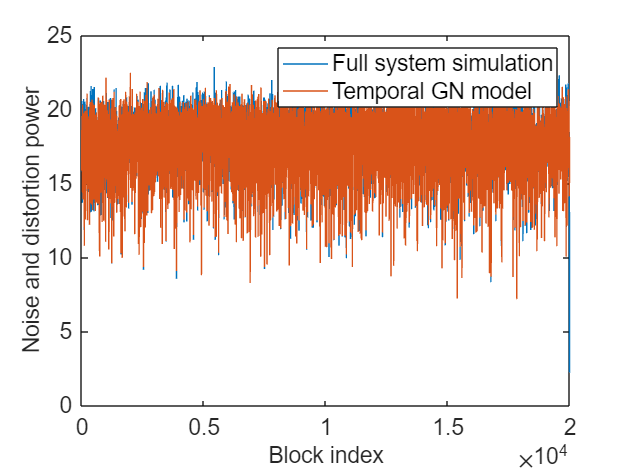

figure();
title("SNR over time")
plot(10*log10(1./sigma_simulation(1:block_length_SNR_evaluation:end)));
hold on;
% plot(sigma_time_varying(1:block_length_SNR_evaluation:end));
plot(10*log10(1./sigma_TGN(1:block_length_SNR_evaluation:end)));
legend(["Full system simulation","Temporal GN model"])
% legend(["Full system simulation","Calculated time varying distortion power","Temporal GN model"])
xlabel("Block index"); ylabel("SNR (dB)"); fontsize(15,"points");

#### Statistical Analysis

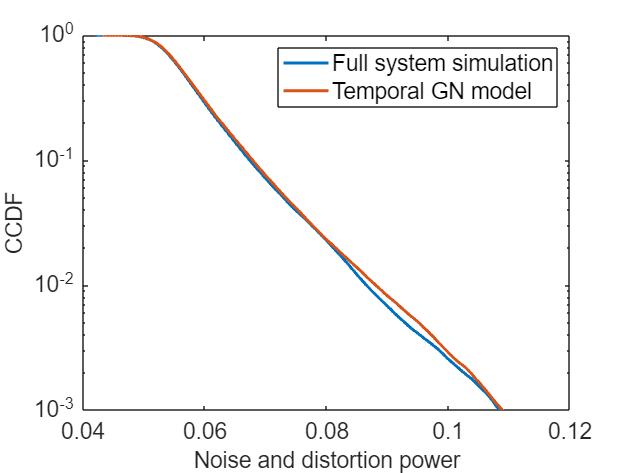

[f_TGN, t_TGN] = ecdf(sigma_TGN);
ccdf_vals_TGN = 1 - f_TGN;
[f_time_varying, t_time_varying] = ecdf(sigma_time_varying);
ccdf_vals_time_varying = 1 - f_time_varying;
[f_sim, t_sim] = ecdf(sigma_simulation);
ccdf_vals_simulation = 1 - f_sim;
figure();
title("Statistical analysis")
semilogy(t_sim, ccdf_vals_simulation,"LineWidth",2); hold on; semilogy(t_TGN, ccdf_vals_TGN,"LineWidth",2); % semilogy(t_time_varying, ccdf_vals_time_varying);
legend(["Full system simulation","Temporal GN model"])
% legend(["Full system simulation","Calculated time varying distortion power","Temporal GN model"])
xlabel("Noise and distortion power"); ylabel("CCDF"); ylim([1e-3 1]); fontsize(15,"points");

#### Final comments

Note that this code slightly differs from the code used for the paper and the experiment. For example, we measure the phase noise realization in the paper. Further, the paper also includes experimental results, adaptive DSP, dual pol, etc...

If you should have any questions, comments, or remarks, please contact [benedikt.geiger@kit.edu](https://www.cel.kit.edu/team_geiger.php).

Written by Benedikt Geiger, September 2025.